3.22 & 3.23

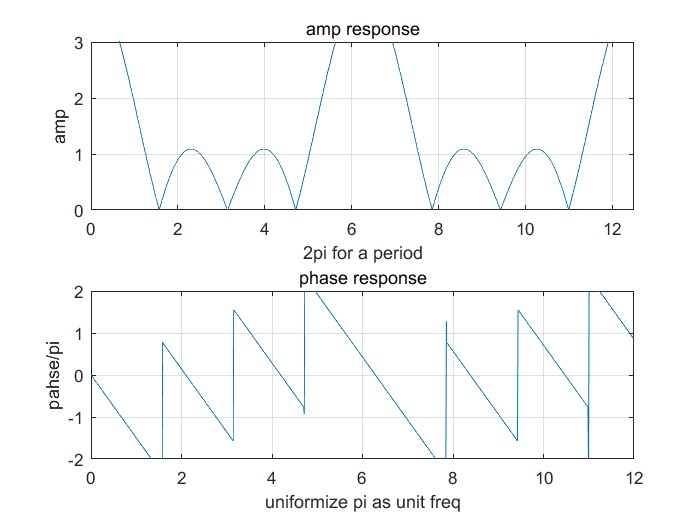

figure(1);
y = zeros(1,51);
y(1:4) = 1;
k = 0:1000;
n = 0:50;
w=2*pi/500*k;
X=y*exp(-1i.*n'*w);
subplot(2,1,1),plot(w,abs(X)),title('amp response'),grid,ylabel('amp'),xlabel('2pi for a period');
axis([0 12.5 0 3]);
subplot(2,1,2),plot(w,angle(X)),title('phase response'),grid,ylabel('pahse/pi'),xlabel('uniformize pi as unit freq');
axis([0 12 -2 2])

Length = 4 DFT

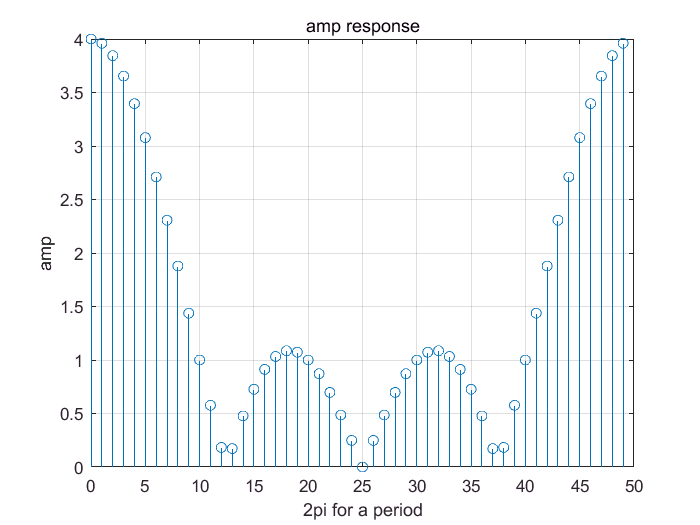

figure(2);
x = 0:49;
result_dft_4 = dft(y(1:50),50);
stem(x,abs(result_dft_4)),title('amp response'),grid,ylabel('amp'),xlabel('2pi for a period');